# Practica 1


model='Pendulo';
ParIn={'x0','y0','k','w'};
Ranges=[-pi pi; -1 1; 0.1 0.5; 1 1.5];
nominal=[0 0 0.3 1.25];
output={'X(t)','Y(t)'};
T = gsua_dataprep(model,Ranges,ParIn,'nominal',nominal,'out_names', output)

y=gsua_eval(T.Nominal,T,0:0.1:100);

M = gsua_dmatrix(T,100,'Show','on');

gsua_ua(M,T,'Parallel',false);

## Linealización (Práctica 2)

model='Pendulo1';
ParIn={'x0','y0','k','w'};
Ranges=[-pi pi; -1 1; 0.1 0.5; 1 1.5];
% out_names={'X(t)', 'Y(t)'};
T = gsua_dataprep(model,Ranges,ParIn)

syms x y k w gamma t theta
%theta= w*t
eq1=y;
eq2=x- k*y - x^3 + gamma*cos(theta);
eq3=w;
z=vpasolve(eq1==0,eq2==0,eq3==0,x,y,w)

eqs=[eq1;eq2;eq3]

vars=[x y theta];
ja1=jacobian(eqs,vars)

ja1=subs(ja1,{'x','k','gamma','theta'},{1.12, 0.3, 0.3,0})
eig(ja1)
eig(ja1)
theta=w*t

ja2=jacobian(eqs,gamma)
w=0
ja2=subs(ja2,{w})

A=double(ja1)
A=A(1:2,1:2);
B=double(ja2)
B=B(1:2)
B=[1;
   0];
C=transpose(B)
D=zeros(2,1)

## Control (Practica 3)

%NO INFLUYE CON [0 1 0]
syms s t
G=[1 0]*inv(s*eye(2)-A)*B

$$G = \frac{125\,\left(10\,s+3\right)}{1250\,s^{2}+375\,s+3454}$$

[Pn,Pd]=numden(G)

$$Pn = 1250\,s+375$$

$$Pd = 1250\,s^{2}+375\,s+3454$$

syms k
Pch=Pd+k*Pn

$$Pch = 375\,s+1250\,s^{2}+k\,\left(1250\,s+375\right)+3454$$


% KK=1.4632


% K=place(A,B,[-0.1,-0.1,-0.1])


inv((s*eye)-A)

## Analisis de Sensibilidad

% Para ver análisis vectorial use method Xiao, y escalar el Saltelli

syms x(t) y(t) k w gamma t theta(t)

eq1= diff(x) == y;
eq2= diff(y) == x- k.*y - x^3 + gamma.*cos(theta);
eq3= diff(theta) == w;
odes=[eq1; eq2; eq3];
vars=[x y theta];
domain=[0 100];
modelName='Penduloo';
[T,solver]=gsua_dataprep(odes,vars,domain,modelName)

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccc} x\left(t\right) & y\left(t\right) & \theta \left(t\right) & \gamma & k & w \end{array}\right)$$

T = 6×2 table
              Range     Nominal
              ______    _______

    x0        0    0       0   
    y0        0    0       0   
    theta0    0    0       0   
    gamma     0    0       0   
    k         0    0       0   
    w         0    0       0   


solver = function_handle with value:
    @(init,pars)ode45(@(t,Y)odefun(t,Y,pars),domain,[Table.Range(fixvars,1)',init],opt)


Ranges=[-pi pi; -1 1; -pi pi ; 0 1; 0.1 0.5; 1 1.5];
[T,solver]=gsua_dataprep(odes,vars,domain,modelName, 'range',Ranges)

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccc} x\left(t\right) & y\left(t\right) & \theta \left(t\right) & \gamma & k & w \end{array}\right)$$

T = 6×2 table
                    Range           Nominal
              __________________    _______

    x0        -3.1416     3.1416        0  
    y0             -1          1        0  
    theta0    -3.1416     3.1416        0  
    gamma           0          1      0.5  
    k             0.1        0.5      0.3  
    w               1        1.5     1.25  


solver = function_handle with value:
    @(init,pars)ode45(@(t,Y)odefun(t,Y,pars),domain,[Table.Range(fixvars,1)',init],opt)


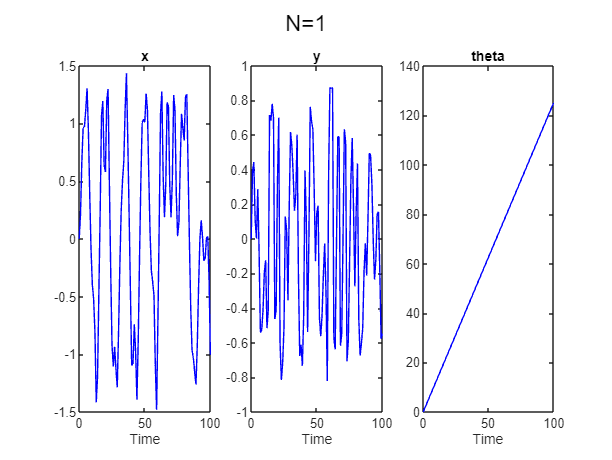

ans =          0    0.2156    0.6661    0.9632    0.9691    1.1171    1.3054    0.9438    0.3957   -0.0830   -0.3944   -0.5219   -0.8088   -1.4154   -1.1858   -0.4555    0.2512    1.0665    1.1941    0.6380    0.5791    1.1958    1.2982    0.4856   -0.2669   -0.9195   -1.1060   -0.9365   -1.1246   -1.2863   -0.8042   -0.2187    0.2431    0.5031    0.6699    1.1203    1.4352    0.8741    0.2441   -0.4237   -1.0973   -1.0774   -0.7412   -0.9801   -1.3936   -0.8816   -0.1548    0.5042    1.0060    1.0386
         0    0.3886    0.4436    0.1116    0.0019    0.2860   -0.0681   -0.5417   -0.5254   -0.4157   -0.1958   -0.1235   -0.5159   -0.4113    0.7145    0.6826    0.7795    0.6983   -0.4632   -0.4131    0.3263    0.6990   -0.6033   -0.8153   -0.7164   -0.5091    0.1291    0.0500   -0.3552    0.1972    0.6166    0.5348    0.3718    0.1615    0.2536    0.6022   -0.2087   -0.6773   -0.6126   -0.7339   -0.4492    0.3946    0.1097   -0.5385    0.0165    0.7632    0.6790    0.6327    0.2881   


gsua_eval(T.Nominal, T)

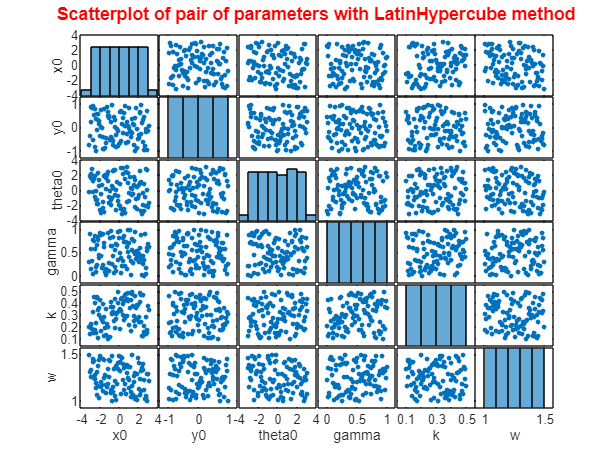


M=gsua_dmatrix(T,100,'Show','on'); %Muestrea de forma uniforme el espacio de factores

T.Properties.CustomProperties.output=2

T = 6×2 table
                    Range           Nominal
              __________________    _______

    x0        -3.1416     3.1416        0  
    y0             -1          1        0  
    theta0    -3.1416     3.1416        0  
    gamma           0          1      0.5  
    k             0.1        0.5      0.3  
    w               1        1.5     1.25  


Tsa=gsua_sa(M,T,'parallel',false,'SensMethod','Saltelli');

Progress: 13%
Estimated processing time (h:m:s): 0:0:4
Remaining time (h:m:s): 0:0:3
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 22:25:43
Number of simulations: 400
Progress: 25%
Estimated processing time (h:m:s): 0:0:4
Remaining time (h:m:s): 0:0:3
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 22:25:43
Number of simulations: 400
Progress: 38%
Estimated processing time (h:m:s): 0:0:3
Remaining time (h:m:s): 0:0:2
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 22:25:43
Number of simulations: 400
Progress: 50%
Estimated processing time (h:m:s): 0:0:3
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 22:25:43
Number of simulations: 400
Progress: 63%
Estimated processing time (h:m:s): 0:0:3
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:2
Estimated stop time (h:m:s): 22:25:42
Number of simulations: 400
Progress: 75%
Estimated processing time (h:m:s): 0:0:3
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0

Tsa

%Indice de confiabilidad
confiabilidad=sum(Tsa.Si)/sum(abs(Tsa.Si))


gsua_plot('Pie',Tsa,Tsa.STi);

figure(1)
clf
gsua_plot('Bar', Tsa,Tsa.STi)

length(Tsa.STi_vec(1,:))

figure(2)
clf
gsua_plot('TotalSensitivityArea',Tsa,Tsa.STi_vec,0:100)

xdata=0:100;
T.Properties.CustomProperties.output=2;
[Tsa,Y,J]=gsua_sa(M,T,'parallel',false,'SensMethod','Saltelli','xdata',xdata)

%Análisis de Incertidumbre
figure(3)
clf
gsua_plot('UncertaintyAnalysis',Tsa,Y,xdata)

figure(4)
clf
gsua_plot('FractionalSensitivityArea',Tsa,Tsa.STi_vec,xdata);

%Análisis para una curva en particular